# Create and Customize 3-D Quiver Plots

3-D quiver plots create arrows with varying directions and lengths that signify flow magnitude at specified 3-D Cartesian coordinates.

### Create Data

Use *meshgrid *and *surfnorm *in a helper function to generate data for 3-D quiver plots representing the functions $z=-0\ldotp 5*\left(x^2 +y^2 \right)$ and $z=-x*y$.

[X,Y,Z1,U1,V1,W1,Z2,U2,V2,W2] = createData();

### Basic Quiver Plot

Visualize vectors normal to the surface of the function $z=-0\ldotp 5*\left(x^2 +y^2 \right)$.

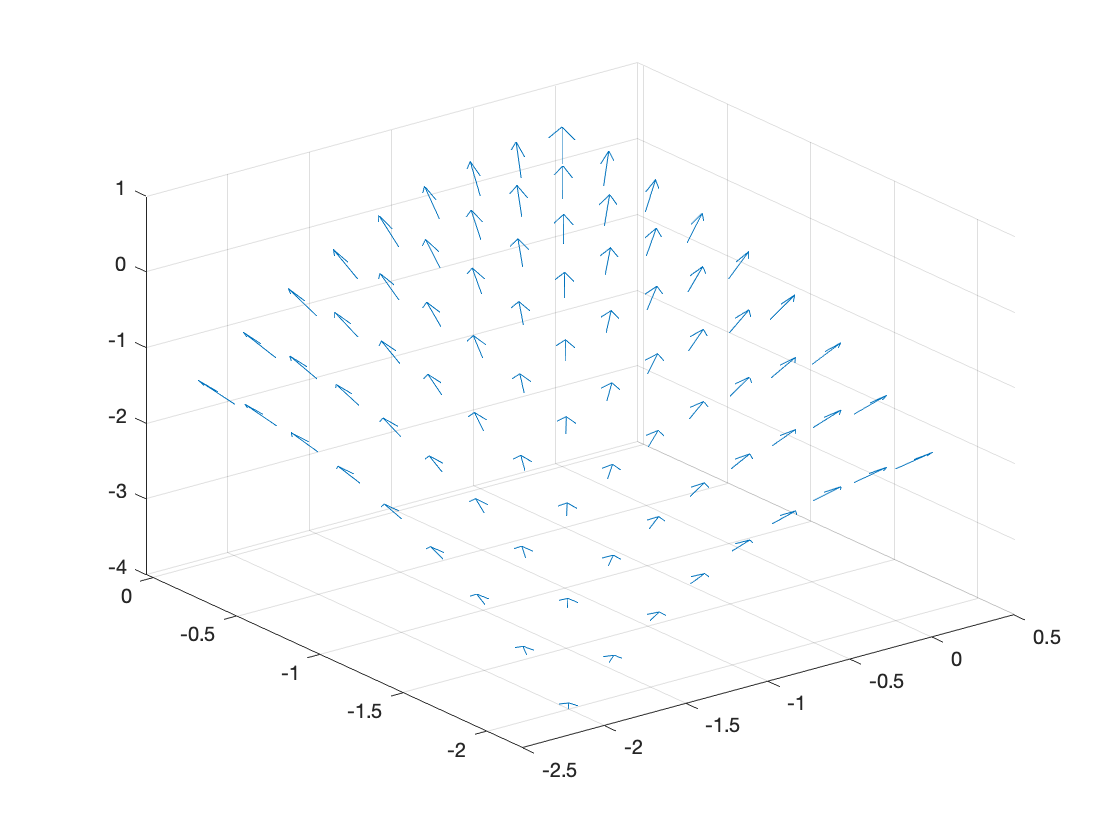

quiver3(X,Y,Z1,U1,V1,W1);

## Customization

### Modify Arrow Head and Marker

Use Name, Value pairs to modify the *ShowArrowHead* and *Marker *fields. Use *axis equal* to acheive a uniformly scaled visualization of the vector field.

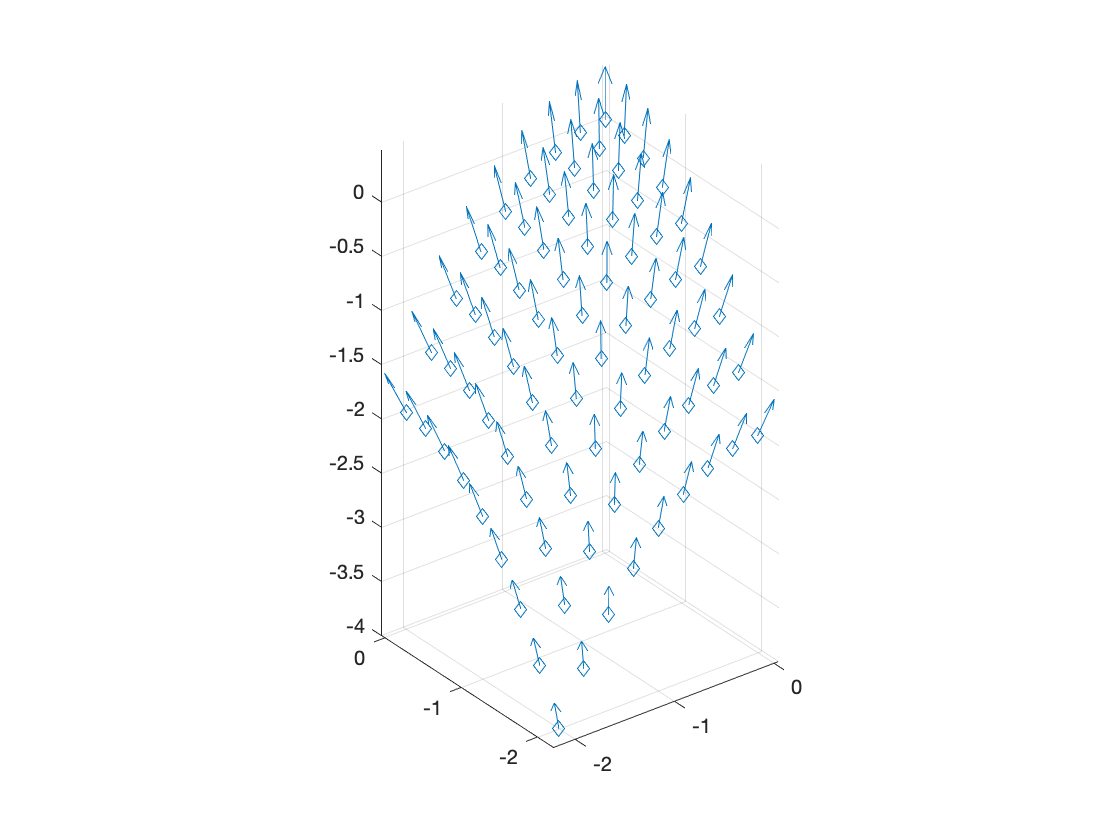

showArrowHead = "on";
MarkerType = 'd';

q = quiver3(X,Y,Z1,U1,V1,W1,...
    "ShowArrowHead",showArrowHead,...   % Specify if arrow heads show
    "Marker",MarkerType);               % Specify marker type
axis equal

### Specify Arrow Color

Use the 7th input to `quiver3` to specify the arrow color. Specify the width of the arrow stem and head using the *LineWidth* Name, Value pair argument.

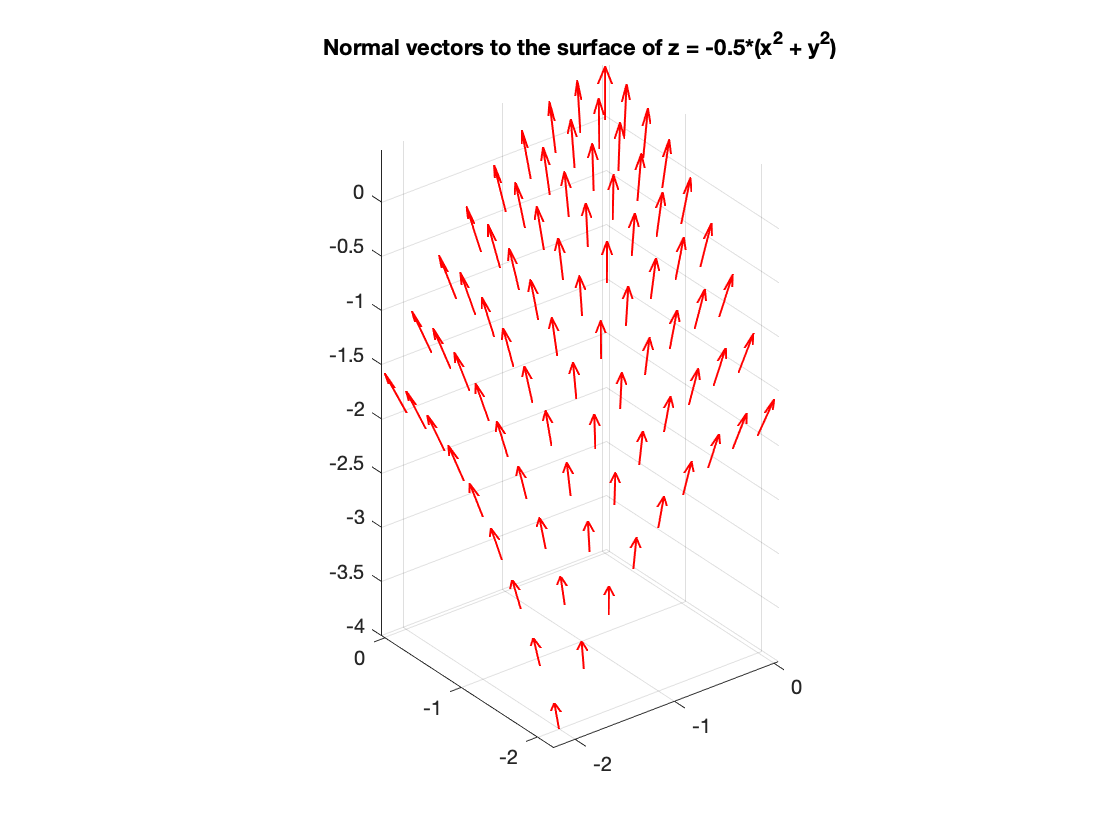

ArrowColor = 'r';
LineWidth = 1;

figure
q1 = quiver3(X,Y,Z1,U1,V1,W1,...
    ArrowColor,...          % Specify an arrow color as the 7th input
    "LineWidth",LineWidth); % Specify the line width of the arrow stem and head
axis equal
title("Normal vectors to the surface of z = -0.5*(x^{2} + y^{2})")

### Specify Axes for 3-D Quiver Plot

Use *tiledlayout* to plot multiple plots in one figure on separate axes. Add titles and axes labels to both axes.

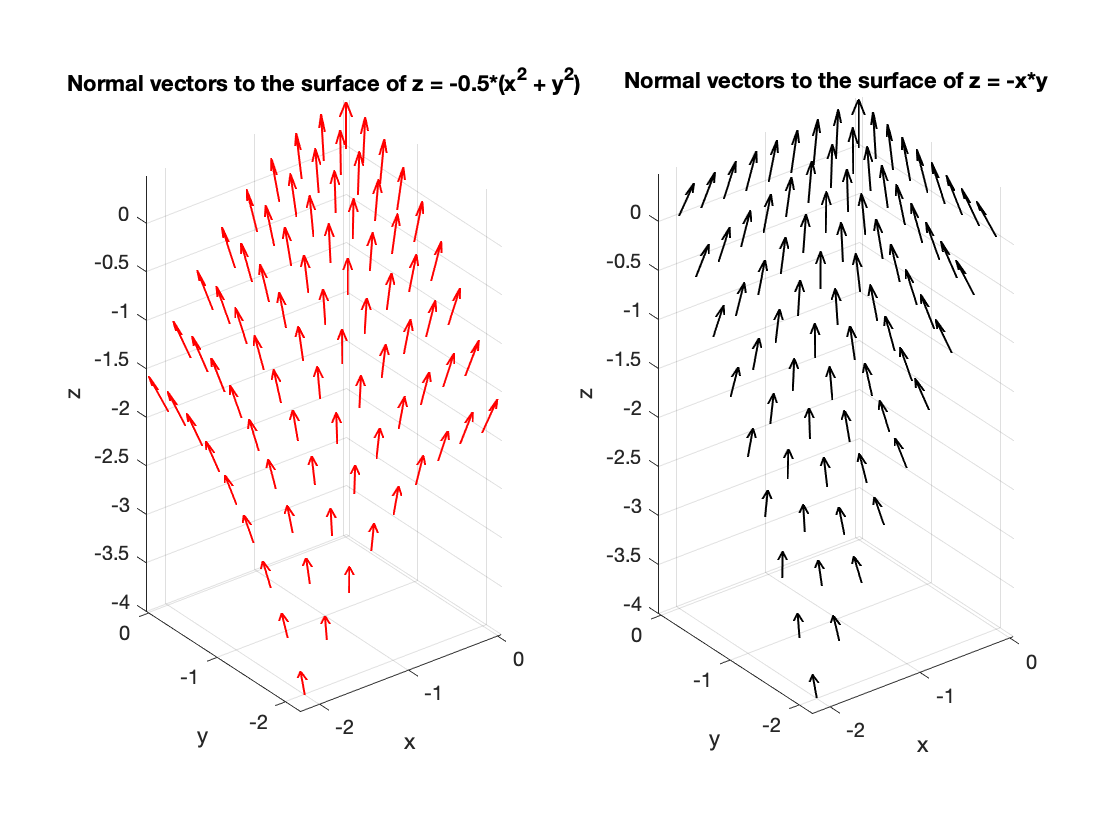

figure
tiledlayout(1,2)

% Left plot
ax1 = nexttile;
q2 = quiver3(ax1,X,Y,Z1,U1,V1,W1,...
    'r',...                             % Specify arrow color
    "LineWidth", 1);                    % Specify line width
axis equal
title(ax1,"Normal vectors to the surface of z = -0.5*(x^{2} + y^{2})")
xlabel("x"); ylabel("y"); zlabel("z");

% Right plot
ax2 = nexttile;
q3 = quiver3(ax2,X,Y,Z2,U2,V2,W2,...
    'k',...                             % Specify arrow color
    "LineWidth", 1);                    % Specify line width
axis equal
title(ax2,"Normal vectors to the surface of z = -x*y")
xlabel("x"); ylabel("y"); zlabel("z");

## **Additional Information**

### **Get All Quiver Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Quiver Object, uncomment the following line of code.

% get(q)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[quiver3](https://www.mathworks.com/help/matlab/ref/quiver3.html)

### Helper Function

This function generates x, y, z, u, v, w data for two surfaces given by $z=-0\ldotp 5*\left(x^2 +y^2 \right)$ and $z=-x*y$. u, v and w values represent vectors normal to each of the surfaces.

function [X,Y,Z1,U1,V1,W1,Z2,U2,V2,W2] = createData()
    [X,Y] = meshgrid(-2:0.25:0,-2:0.25:0);
    Z1 = -0.5*(X.^2 + Y.^2);
    [U1,V1,W1] = surfnorm(Z1);
    Z2 = -X.*Y;
    [U2,V2,W2] = surfnorm(Z2);
end

Copyright (c) 2021, The MathWorks, Inc.